R = 3.3;
L = 1.25e-3;
kt = 0.0285;
ke = kt;
J = 1.12e-6;
B = 6.56e-5;
m_rod = 0.035;
r_rod = 4e-3;
J_rod = 1/2*m_rod*r_rod^2;
r1_pulley = 15.8e-3/2;
r2_pulley = 4e-3;
m_pulley = 0.005;
J_pulley = 1/2 * m_pulley * (r1_pulley^2 + r2_pulley^2)

J_pulley = 1.9603e-07


mdl = 'motor_m_china';
TF = minreal(tf(linearize(mdl, getlinio(mdl))));
G_dtheta = TF(1);
G_theta = TF(2);
disp(['Dc gain of dtheta:', num2str(dcgain(G_dtheta))])

Dc gain of dtheta:47.8373


disp(['Dc gain of theta:', num2str(dcgain(G_theta))])

Dc gain of theta:Inf


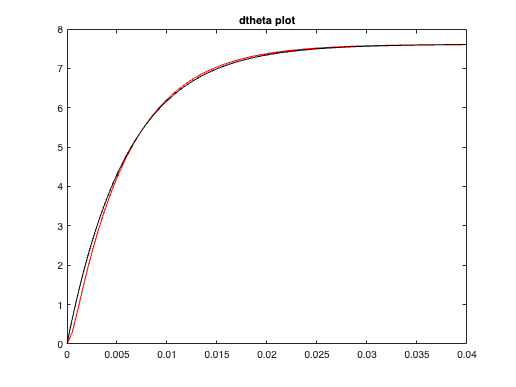

[y1, t1] = step(G_dtheta, 0.2);
[y2, t2] = step(G_theta);
t = 0:0.0001:0.2;
e = y1(end)/(2*pi)*(1-exp(-1/6e-3*t));
figure;
plot(t1, y1/(2*pi), '-r', t, e, 'k');
title('dtheta plot')
xlim([0 0.04])